# PRÁCTICA SW2

#### Maria José Medina y Teresa González

## 1. Introducción

En esta práctica se resolverá la ecuación de Helmholtz o ecuación de dispersión, la cual cumplen todos los modos guiados en una fibra, y sirve para obtener la constante de propagación beta en función de varios parámetros, en concreto de la constante de propagación normalizada (b). Para encontrar las soluciones de esta ecuación (f(b)=0) de forma numérica, se utilizará el método de bisección de la práctica anterior. Con estas soluciones se representarán los diferentes modos de funcionamiento de la fibra óptica en función de la frecuencia normalizada.

A continuación verificará la expresión aproximada de la constante de probagación normalizada (b).

Por último se calculará tanto el radio modal ($\omega_o$) como el factor de confinamiento en función de la frecuencia normalizada (V) y se estudiarán sus implicaciones en materia de eficiencia en potencia.

## 2. Análisis de la ecuación de Helmholtz

En este apartado, se analizará el comportamiento de la ecuación, variando en distintos casos la frecuencia normalizada (V) y la variación angular del perfil del campo (l). Este análisis se realizará partir de la representación del valor de la ecuación en función del parámetro b y el cálculo de las raíces. Se estraerán conclusiones para cada caso.

Se utilizará un vector b entre 0 y 1, ya que es un valor normalizado. Además, los parámetros tendrán los siguientes valores:

- a=$5\cdot 10^{-6}$

- n1=1.46

- n2= 1.456

####  Caso {V=5 y l=0}

Se representa la función Helmholtz y se obtienen las raíces. En este caso, ya que V=5, V >2.405, la fibra es multimodo, por lo que se esperan soluciones para distintas l's.

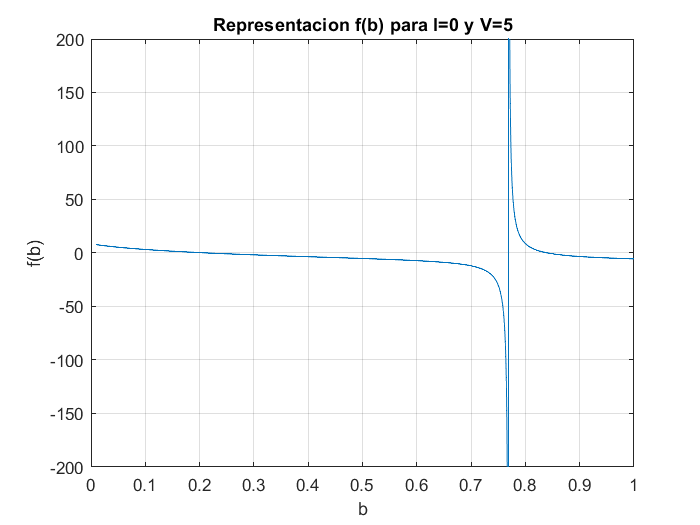

%vector b
b= 0.01:0.00001:1;

%Parámetros
V=5;
l=0;
a=5e-6;
n1=1.46;
n2=1.456;

%Función 
y=helmholtz_equation(V, b, l, a, n1, n2);

%Representación
figure
plot(b,y)
ylim([-200,200])
grid on
xlabel("b")
ylabel("f(b)")
title("Representacion f(b) para l=0 y V=5")

Como se puede ver, se encuentran 2 raíces en b=0.2 y b=0.85 aproximadamente, correspondientes a dos picos de potencia en en núcleo. Aunque en la gráfica aparece otro cruce en 0 entre b=0.7 y b=0.8, este se trata de una representación errónea de una asíntota debido a que Matlab asume que la función es contínua.

A continuación, se calculan las raíces con el método de la bisección, teniendo en cuenta los intervalos donde se esperan encontrar las mismas. Los intervalos escogidos han sido [0.001, 0.7] para la raíz primera u [0.8005, 1] para la segunda. Se escogen unos valores de tolerancia de $10^{-5}$ y $10^6$ repeticiones.

r=a; %radio
iter=1e06;
tol=1e-05;
f='helmholtz_equation';

%raices l=0;

%Intervalo a la izquierda
a=0.001;
b=0.7;
x0= myBisection_helmholtz(f,a,b, V, l, r, n1, n2, iter, tol)

x0 = 0.2157


%Intervalo a la derecha
a=0.8005;
b=1;
x0= myBisection_helmholtz(f,a,b, V, l, r, n1, n2, iter, tol)

x0 = 0.8411

Se comprueba que las soluciones calculadas coinciden con las observadas en la gráfica, por lo que el método de bisección funciona correctamente.

####  Caso {V=5 y l=1}

Se repite el proceso anterior con l=1. El resto de parámetros se mantienen.

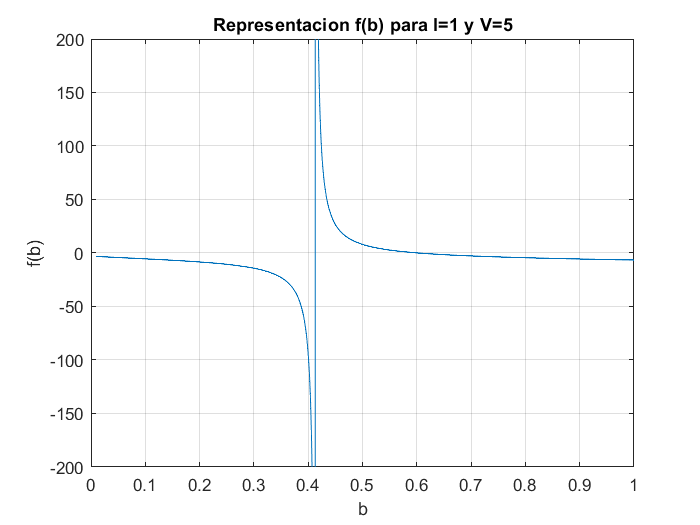

%Parámetros
b= 0.01:0.00001:1;
a=5e-6;
l=1;
y=helmholtz_equation(V, b, l, a, n1, n2);

%Representación
figure
plot(b,y)
ylim([-200,200])
grid on
xlabel("b")
ylabel("f(b)")
title("Representacion f(b) para l=1 y V=5")

Se observa que en este caso solo hay una raíz a la derecha de la asíntota, la cual está en torno a b=0.6, por lo que solo hay un modo de propagación. A la izquierda de esta, no se encuentra ninguna raíz. Se ignora la asíntota, como ya se ha explicado.

A continuación, se calcula la raíz analíticamente mediante el método de bisección, dentro del intervalo [0.5,1].

%raices l=1
% Intervalo derecha
a=0.5;
b=1;
x0= myBisection_helmholtz(f,a,b, V, l, r, n1, n2, iter, tol)

x0 = 0.6027

Efectivamente, la raíz calculada coincide con la esperada.

Se repite el cálculo dentro del intervalo [0.01,0.3], en el que de acuerdo con la representación, no hay ninguna raíz.

%Intervalo izquierda
a=0.01;
b=0.3;
%x0= myBisection_helmholtz(f,a,b, V, l, r, n1, n2, iter, tol)

Con el método no se encuentran raíces en este intervalo , tal y como se esperaba tras su representación.

En resumen, de estos dos casos se concluye que, debido a la propagación multimodo (V=5),  se encuentran soluciones tanto para l=0 (2 soluciones) como para l=1 (1 solución). En el caso de l=0, se estan propagando dos modos simultáneamente superpuestos. Para l=1, la única solución se identifica como LP11.

#### - Caso {V=2 y l=0}

Se representa la función de Helmholtz y se calculan las raíces para los nuevos parámetros. En este caso, ya que V<2.405, la fibra funciona en monomodo (LP01, modo fundamental)

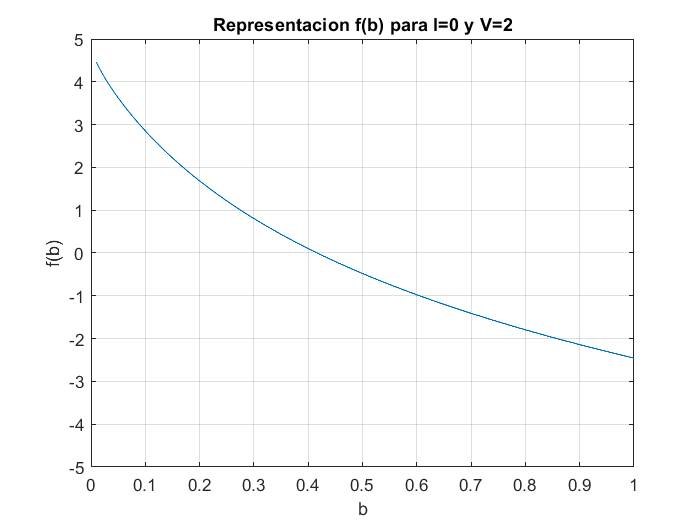

%Parámetros
V=2;
l=0;
b= 0.01:0.00001:1;
a=5e-6;

%Función
y=helmholtz_equation(V, b, l, a, n1, n2);

%Representación
figure
plot(b,y)
ylim([-5,5])
grid on
xlabel("b")
ylabel("f(b)")
title("Representacion f(b) para l=0 y V=2")

Se observa que solo hay una raíz en torno a b=0.4. Por tanto, esta raíz corresponde al modo fundamental (LP01).

A continuación, se calcula la raíz numéricamente con el método de bisección, en el intervalo [0.01,1].

%Intervalo
a=0.01;
b=1;

%Raíz
x0= myBisection_helmholtz(f,a,b, V, l, r, n1, n2, iter, tol)

x0 = 0.4165

De nuevo, se comprueba que el método encuentra la misma raíz que la esperada a partir de la representación.

Se calcula la constante de propagación ($\beta$) y la longitud de onda de propagación en el vacío ($\lambda_o$)  a partir de la solución encontrada (x0).

%Radio
a=5e-6;

%Cálculo lamda0
lamda0= 2*pi*a*sqrt(n1^2-n2^2)/V

lamda0 = 1.6965e-06


0=2*pi/lamda0;

%Cálculo beta
beta= (x0.*(n1-n2) + n2)*k0

beta = 5.3988e+06

#### - Caso {V=2 y l=1}

Se representa la función de Helmholtz para comprobar que, para una variación angular del perfil de campo (l) igual a 1, no se encontrarán raíces,  de acuerdo con las gráficas b-V, ya que LP1X no corresponde al modo fundamental y 2 se encuentra por debajo del umbral de funcionamiento monomodo.

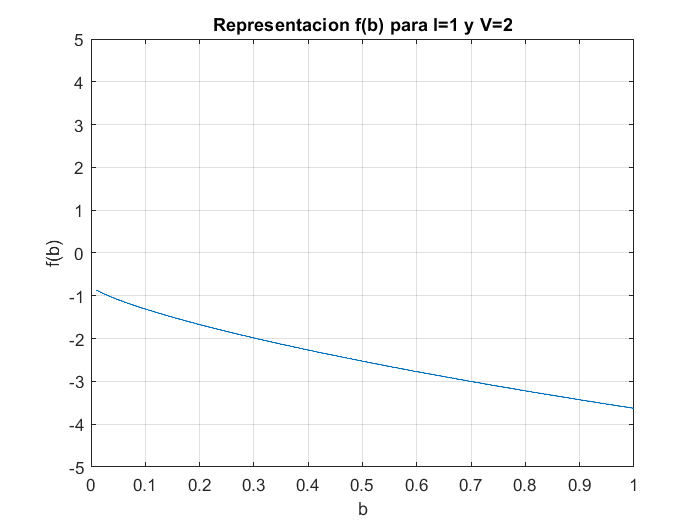

%Parámetros
V=2;
l=1;
b= 0.01:0.00001:1;
a=5e-6;

%Funcion
y=helmholtz_equation(V, b, l, a, n1, n2);

%Representacion
figure
plot(b,y)
ylim([-5,5])
grid on
xlabel("b")
ylabel("f(b)")
title("Representacion f(b) para l=1 y V=2")

Se comprueba que no existen soluciones, al no ser LP1X el modo fundamental.

####  - Caso {V=3 y l=1}

Se repite el proceso de representación y cálculo de las soluciones para la nueva combinación de parámetros. En este caso, V>2.405 (V=3), por lo que la propagación es multimodo, y se encuentra solución para distintas l's.

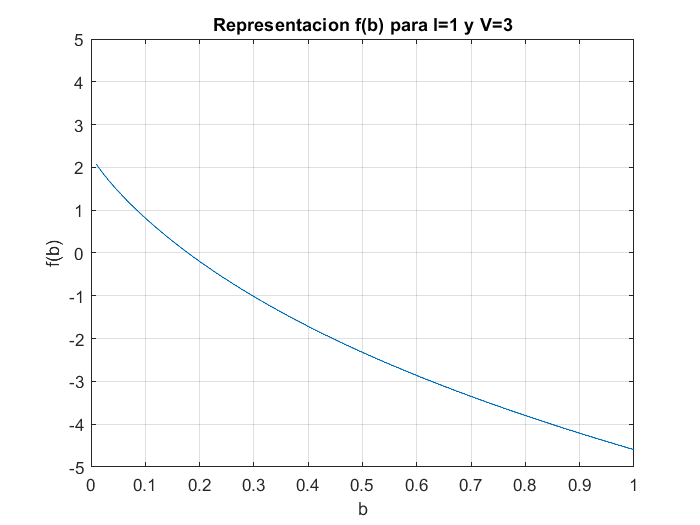

%Parámetros
V=3;
l=1;
b= 0.01:0.00001:1;
a=5e-6;

%Función
y=helmholtz_equation(V, b, l, a, n1, n2);

%Representación
figure
plot(b,y)
ylim([-5,5])
grid on
xlabel("b")
ylabel("f(b)")
title("Representacion f(b) para l=1 y V=3")

Se observa una única raíz dentro del intervalo [0,1], en torno a b= 0.18. De acuerdo con las gráficas b-V, esta solución corresponde a LP11.

A continuación, se calcula la raíz analíticamente con el método de bisección:

%Raíz
a=0.01;
b=1;
x0= myBisection_helmholtz(f,a,b, V, l, r, n1, n2, iter, tol)

x0 = 0.1787

La raíz calculada coincide con la observada.

Se calcula la constante de propagación ($\beta$) y la longitud de onda de propagación en el vacío ($\lambda_o$),  a partir de la solución encontrada (x0)

%Radio
a=5e-6;

%Cálculo lamda0
lamda0= 2*pi*a*sqrt(n1^2-n2^2)/V

lamda0 = 1.1310e-06

k0=2*pi/lamda0;

%Cálculo beta
beta= (x0.*(n1-n2) + n2)*k0

beta = 8.0929e+06

## 3. Representación de los modos guiados

En este apartado se representarán los modos guiados desde l=0 hasta l=4, a partir de las curvas b-V. Para ello, se variará el valor de V de 0.1 a 10 (ya que para valores menores a 0.1 no se encuentran soluciones) dentro de un bucle, y se calcularán los puntos de b correspondientes para cada valor de V, en función del orden especificado por el parámetro l. Dichos puntos corresponden a las soluciones de la ecuación de Helmholtz (f(b)=0), y se calcularán mediante el método de bisección.

El intervalo de b's (parámetro normalizado) será [0.01, 0.99], para evitar indeterminaciones.

Los valores de los parámetros utilizados son los siguientes:

- r=$5\cdot 10^{-6}$

- n1=1.46

- n2= 1.456

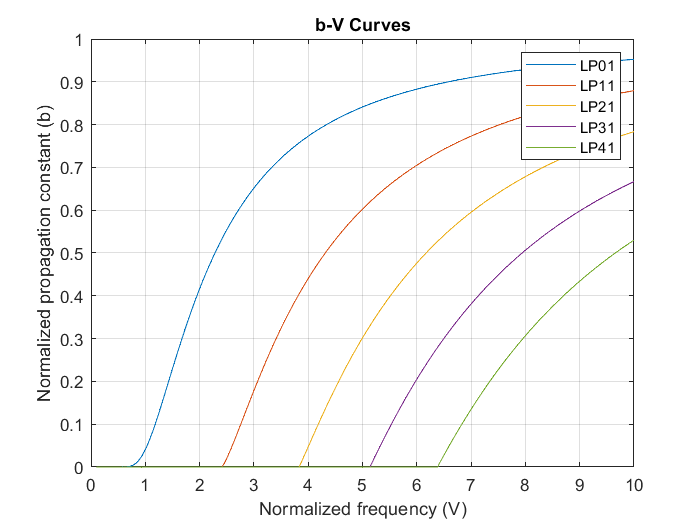

%Radio core
r=5e-6;

%Vector V
V_vec = 0.1:0.01:10 ; 

%Vector l
l_vec = [0 1 2 3 4] ;

%Intervalos
ini_interval = .01;
fin_interval = .99;

%Bucle modos
for l_iter = 1:length(l_vec)
    l = l_vec(l_iter);
    ini_interval = .01;
    
    %Bucle V's
    for V_iter = 1:length(V_vec)
        V = V_vec(V_iter);
        if V_iter ~= 1
            %Se acorta el intervalo despues de encontrar el primer punto,
            %para ir obteniendo todas las soluciones de la curva.
            ini_interval = b0(l_iter,V_iter-1);
        end
        %Se fuerza que la solución sea 0 si se llega al final del intervalo
        test = myBisection_helmholtz(f,ini_interval,fin_interval, V, l, r, n1, n2, iter, tol, 'helm');
        if test >0.98
            b0(l_iter,V_iter)=0;
        else
             %Se guardan las raices de b para cada l y cada V
            b0(l_iter,V_iter) =myBisection_helmholtz(f,ini_interval,fin_interval, V, l, r, n1, n2, iter, tol, 'helm');
        end

    end
end

%Representacion graficas b-V
figure
plot(V_vec,b0)
grid on
xlabel("Normalized frequency (V)")
ylabel("Normalized propagation constant (b)")
title("b-V Curves")
legend ('LP01', 'LP11', 'LP21', 'LP31', 'LP41');

Se obtienen las gráficas b-V explicadas en teoría, en las que para cada LP se obtiene un valor de b en función de V. En este caso, ya que no se varía la m (1 pico de $J_l$), se obtienen las curvas LP_X1. 

Se aprecia claramente cómo para valores de V<2.405, se obtiene un único valor de b correspondiente a LP01, que es el modo fundamental, ya que la propagación es monomodo. A partir de valores de V mayores, hay múltiples soluciones correspondientes a distintos modos, lo que causará dispersión intermodal, ya que cada modo seguirá un camino distinto a través del core. Por ejemplo, en el caso de V=4, se obtienen 3 valores distintos de b: b=0.8 correspondiente a LP01, b=0.48, correspondiente a LP11 y b=0.05 correspondiente, a LP21, aproximadamente.

A continuación, se muestra la región monomodo, en un intervalo de [0.2.45]:

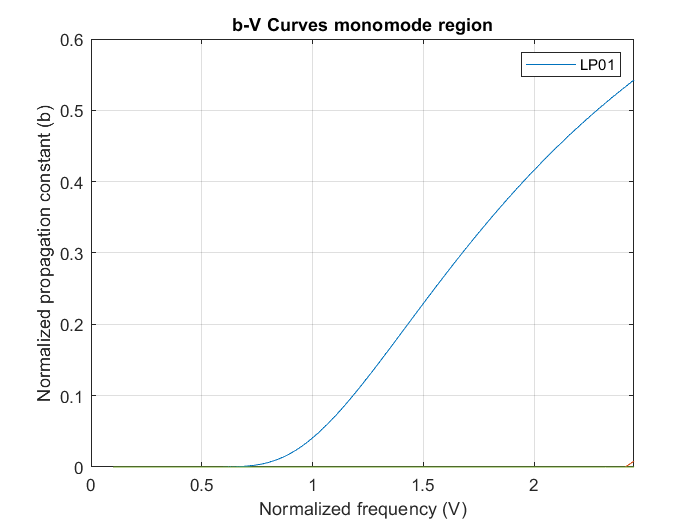

%Representacion graficas b-V monomodo
figure
plot(V_vec,b0)
grid on
xlabel("Normalized frequency (V)")
xlim([0,2.45])
ylabel("Normalized propagation constant (b)")
title("b-V Curves monomode region")
legend('LP01')

Se demuestra que la única curva en esta región corresponde al modo fundamental. Por ejemplo, para un V=1.5, el valor de b= 0.25 aproximadamente.

## 4. Aproximación para el cálculo de la constante de propagación normalizada

En este apartado, se calcula de forma aproximada el valor de b para el modo fundamental LP01 (propagación monomodo, l=0), la cual es válida en el rango de V [1.5,2.5]. Se comparará el cálculo aproximado con el exacto, obtenido de las soluciones de la ecuación Helmholtz, como se ha explicado anteriormente.

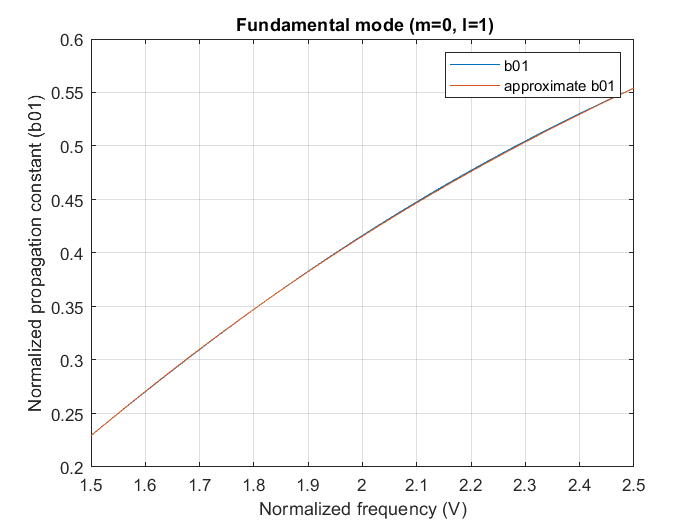

%Vector V rango válido
V_vec=1.5:0.01:2.5;

%Parámetros
l=0;
r=5e-6;
%Inicializar solución
b0=0;

%Intervalo
ini_interval = .01;
fin_interval = .99;

%Bucle V para el cálculo de b01
for V_iter = 1:length(V_vec)
    V = V_vec(V_iter);
    if V_iter ~= 1
        %Se Acorta el intervalo despues de encontrar el primer punto
        ini_interval = b0(V_iter-1);
    end
    %Fuerza 0 en el fin del intervalo
    test = myBisection_helmholtz(f,ini_interval,fin_interval, V, l, r, n1, n2, iter, tol, 'helm');
    if test >0.98
        b0(V_iter)=0;
    else
        %Solución exacta para cada V y l=0
        b0(V_iter) =myBisection_helmholtz(f,ini_interval,fin_interval, V, l, r, n1, n2, iter, tol, 'helm');
    end

    %Solucion aproximada
    b0_aprox(V_iter)=aproximated_b01(V);   
end

%Comparacion ambas soluciones 
figure
plot(V_vec,b0)
hold on
plot (V_vec, b0_aprox)
grid on
xlabel("Normalized frequency (V)")
ylabel("Normalized propagation constant (b01)")
title(" Fundamental mode (m=0, l=1)")
legend ('b01', 'approximate b01');

Se observa que ambos vectores de soluciones son prácticamente coincidentes, por lo que dentro del rango de V's válido, la fórmula de aproximación es válida.

Se comprueba que las soluciones son iguales a partir del error cuadrático medio, que es del orden de $10^{-7}$ (aproximadamente 0):

mse = 1/length(b0)*(sum((b0-b0_aprox).^2)) 

mse = 4.6435e-07

## 5. Cálculo del radio modal

En este apartado se calcula el radio modal como medida del confinamiento de cada modo. Este radio es la distancia a la que el campo eléctrico decae en $\frac{1}{e}$ y se puede aproximar mediante la fórmula:


$$\omega_o = a \cdot (0.65 + 1.619 \cdot V^{\frac{-3}{2}} + 2.879 \cdot V ^{-6})$$


Teniendo en cuenta la distribución gaussiana del campo eléctrico, se puede calcular después el fator de confinamiento como

 
$$\Gamma=\frac{P_{core}}{P_{tot}}= \frac{ \int_{0}^{a} r \cdot |E_x|^2 \cdot dr}{\int_{0}^{\infty} r \cdot |E_x|^2 \cdot dr}$$


En primer lugar se ha representado el radio modal $\omega_o$ como función de la frecuencia normalizada V en el intervalo [1.2, 2.4] para un radio del núcleo de $5\cdot10^{-6}$ [m]. A continuación se calcula el factor de confinamiento también en función de la frecuencia normalizada y se representa en la gráfica posterior.

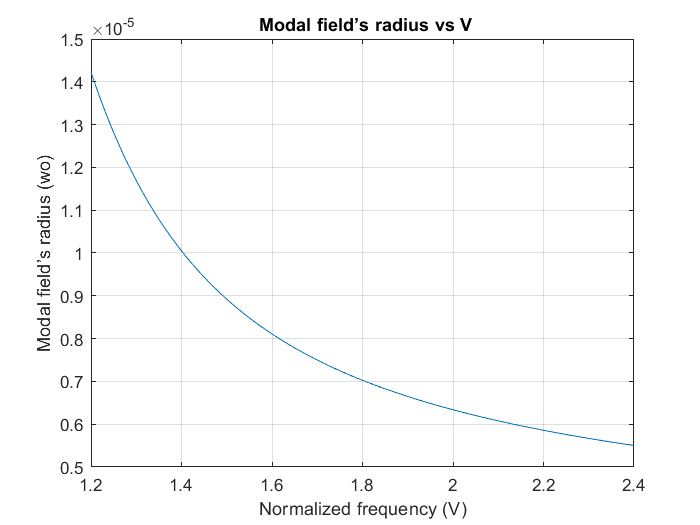

%clear all;
V_vec=1.2:0.01:2.4;
a=5e-6; %radio core

for V_iter = 1:length(V_vec)
    V = V_vec(V_iter);
   wo(V_iter) = aproximated_wo(a,V);
end

figure
plot(V_vec,wo)
grid on
xlabel("Normalized frequency (V)")
ylabel("Modal field’s radius (wo)")
title(" Modal field’s radius vs V")

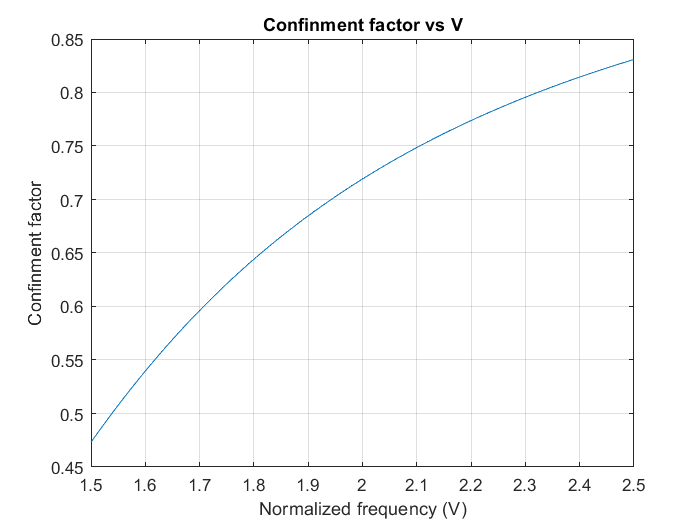

%mayor V, menor landa, caben mas, menor wo

%expresion factor confinamiento
c=125e-6;%radio cladding
r_core=0:1e-7:a;
r_total=0:1e-7:c;

%vector de frecuencia 
V_vec=1.5:0.01:2.5;

wo = 0;

for V_iter = 1:length(V_vec)
    V = V_vec(V_iter);
   wo(V_iter) = aproximated_wo(a,V);
   Ex_mod_core= exp(-(r_core/wo(V_iter) ).^2);
   Ex_mod_total= exp(-(r_total/wo(V_iter)).^2);
   Pcore= sum(Ex_mod_core.^2.*r_core);
   Ptotal= sum(Ex_mod_total.^2.*r_total);
   confinment_factor(V_iter)=Pcore/Ptotal;

end

figure
plot(V_vec,confinment_factor)
grid on
xlabel("Normalized frequency (V)")
ylabel("Confinment factor")
title("Confinment factor vs V")

A la vista de los resultados, se deduce que el radio modal decrece con la frecuencia de forma exponencial (depende sobre todo de $a \cdot V^{\frac{-3}{2}}$). En particular,  En consecuencia, a mayor frecuencia, el factor de confinamiento crece. Esto quiere decir que cuanto menor es la longitud de onda, mayor es la eficiencia en potencia, puesto que interesa que la mayor parte esté concentrada en el núcleo ya que es por donde se realiza la transmisión. Sin embargo, un factor de confinamiento demasiado alto tampoco es ideal ya que si el campo es muy intenso su comportamiento se vuelve no lineal.

Por último, se ha comparado la expresión aproximada del factor de confinamiento $1 - e^{\frac{-2 \cdot a^2}{w_o^2} }$ con la obtenida anteriormente. Para ello, se ha calculado el error cuadrático medio (MSE) entre ellas, el cual queda del orden de $10^{-5}$, por lo que se puede concluir que la aproximación es correcta.

% expresion aproximada del CFs
cf= 1-exp(-2*a^2./wo.^2);
%ERROR CUADRATICO MEDIO
mse = 1/length(cf)*(sum((cf-confinment_factor).^2)) %0  no hay error

mse = 4.7456e-05

## 6. Conclusión

En esta práctica se resuelve las ecuación de Helmholtz o ecuación de dispersión que define los distintos modos de funcionamiento de la fibra óptica. Las raíces de estas ecuaciones para los distintos valores de frecuencia normalizada definen los distintos modos de la fibra óptica. Se han representado estas raíces y se ha verificado tanto el límite de V = 2.405 para su funcionamiento en monomodo como la existencia de más de un pico en el núcleo a partir de cierto umbral de frecuencia normalizada diferente para cada modo.

A continuación se ha verificado que la expresión aproximada de la constante de probagación normalizada (b) es igual a la expresión completa con un MSE del orden de $10^{-7}.$

Por último se han calculado tanto el radio modal ($\omega_o$) como el factor de confinamiento en función de la frecuencia normalizada (V). Se ha concluido que el radio modal decrece de forma exponencial y, en consecuencia, el factor de confinamiento crece con la frecuencia. Esto quiere decir que a menor longitud de onda, mayor es la potencia que se enceuntra en el núcleo, por lo que la transmisión es más eficiente. Sin embargo, es importante notar que un factor de confinamiento demasiado alto causa no linearidades que dificultan la transmisión, por lo que tampoco se recomienda incrementarlo hasta el máximo.